#### **Funkcja 1**

clear all; close all;
syms x y;
f1 = x .* exp(-x.^2 - y.^2)

$$f1 = x\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

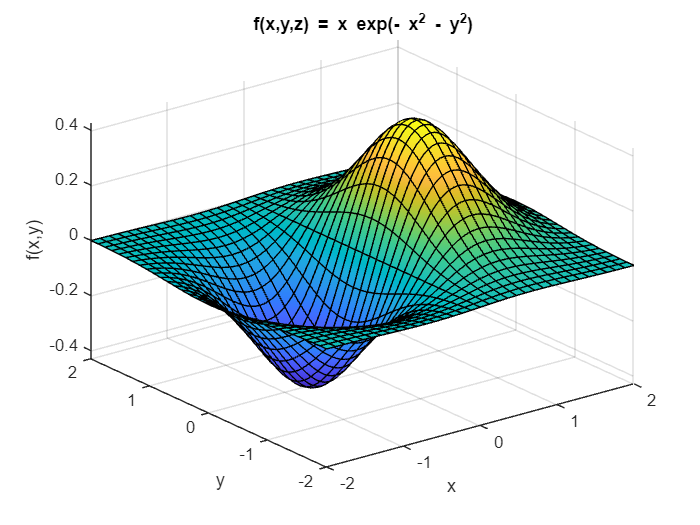

%Wygenerowanie funkcji trójwymiarowej f1
fsurf(f1,[-2,2])
title(['f(x,y,z) = ' texlabel(f1)])
xlabel('x'), ylabel('y'), zlabel('f(x,y)')

%Obliczenie gradientu
gradf = gradient(f1)

$$gradf = \left(\begin{array}{c} {\mathrm{e}}^{-x^{2}-y^{2}}-2\,x^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}\\ -2\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}} \end{array}\right)$$

extreme = solve(gradf == 0)

extreme = struct with fields:
    x: [2×1 sym]
    y: [2×1 sym]


extreme.x

$$ans = \left(\begin{array}{c} -\frac{\sqrt{2}}{2}\\ \frac{\sqrt{2}}{2} \end{array}\right)$$

extreme.y

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

%Obliczenie  Hessianu 
H = jacobian(gradf, [x, y])

$$H = \begin{array}{l} \left(\begin{array}{cc} 4\,x^{3}\,\sigma_{1}-6\,x\,\sigma_{1} & 4\,x^{2}\,y\,\sigma_{1}-2\,y\,\sigma_{1}\\ 4\,x^{2}\,y\,\sigma_{1}-2\,y\,\sigma_{1} & 4\,x\,y^{2}\,\sigma_{1}-2\,x\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

H = hessian(f1,[x, y])

$$H = \begin{array}{l} \left(\begin{array}{cc} 4\,x^{3}\,\sigma_{1}-6\,x\,\sigma_{1} & 4\,x^{2}\,y\,\sigma_{1}-2\,y\,\sigma_{1}\\ 4\,x^{2}\,y\,\sigma_{1}-2\,y\,\sigma_{1} & 4\,x\,y^{2}\,\sigma_{1}-2\,x\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

%Analiza pierwszego punktu ekstremalnego
H1 = double(subs(H, [x, y], [extreme.x(1), extreme.y(1)]))

H1 =     1.7155         0
         0    0.8578


if issymmetric(H1) 
    fprintf('Macierz jest symetryczna (kryterium Sylvestera spełnione).\n');
else
    fprintf('Macierz nie jest symetryczna (kryterium Sylvestera niespełnione).\n');
end

Macierz jest symetryczna (kryterium Sylvestera spełnione).


if H1(1,1) > 0
    fprintf('To kryterium Sylvestera dla głównej minory, który mówi o dodatniej określoności macierzy Hesjana w pierwszym punkcie.\n');
else
    fprintf('To kryterium Sylvestera dla głównej minory, który nie jest spełnione. Macierz Hesjana nie jest dodatnio określona w pierwszym punkcie.\n');
end

To kryterium Sylvestera dla głównej minory, który mówi o dodatniej określoności macierzy Hesjana w pierwszym punkcie.


if det(H1) > 0
    fprintf('To kryterium Sylvestera dla całej macierzy Hesjana, co mówi o dodatniej określoności.\n');
else
    fprintf('To kryterium Sylvestera dla głównej minory, który nie jest spełnione. Macierz Hesjana nie jest dodatnio określona w pierwszym punkcie.\n');
end

To kryterium Sylvestera dla całej macierzy Hesjana, co mówi o dodatniej określoności.


%Analiza drugiego punktu ekstremalnego
H2 = double(subs(H, [x, y], [extreme.x(2), extreme.y(2)]))

H2 =    -1.7155         0
         0   -0.8578


if issymmetric(H2)
    fprintf('Macierz jest symetryczna (kryterium Sylvestera spełnione).\n');
else
    fprintf('Macierz nie jest symetryczna (kryterium Sylvestera niespełnione).\n');
end

Macierz jest symetryczna (kryterium Sylvestera spełnione).


if H2(1,1) < 0
    fprintf('To kryterium Sylvestera dla głównej minory, który mówi o ujemnej określoności macierzy Hesjana w drugim punkcie.\n');
else
    fprintf('To kryterium Sylvestera dla głównej minory, który nie jest spełnione. Macierz Hesjana nie jest ujemnie określona w drugim punkcie.\n');
end

To kryterium Sylvestera dla głównej minory, który mówi o ujemnej określoności macierzy Hesjana w drugim punkcie.


if det(H2) > 0
    fprintf('To kryterium Sylvestera dla całej macierzy Hesjana, co mówi o ujemnej określoności.\n');
else
    fprintf('To kryterium Sylvestera dla głównej minory, który nie jest spełnione. Macierz Hesjana nie jest ujemnie określona w pierwszym punkcie.\n');
end

To kryterium Sylvestera dla całej macierzy Hesjana, co mówi o ujemnej określoności.


#### Funkcja 2 

clear all; close all;
syms x y;
f2 = 0.3*x+0.1*y+(-3.5+0.5*x.^2+0.5*y.^2).^2+100*x .* exp(-x.^2 - y.^2)

$$f2 = \frac{3\,x}{10}+\frac{y}{10}+100\,x\,{\mathrm{e}}^{-x^{2}-y^{2}}+{\left(\frac{x^{2}}{2}+\frac{y^{2}}{2}-\frac{7}{2}\right)}^{2}$$

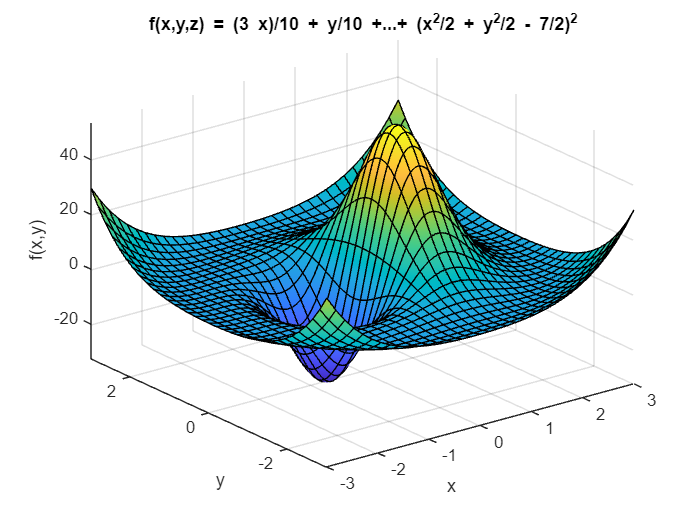

%Wygenerowanie funkcji trójwymiarowej f2

fsurf(f2,[-3,3])
title(['f(x,y,z) = ' texlabel(f2)])
xlabel('x'), ylabel('y'), zlabel('f(x,y)')

%Obliczenie gradientu

gradf = gradient(f2)

$$gradf = \begin{array}{l} \left(\begin{array}{c} 100\,\sigma_{1}-200\,x^{2}\,\sigma_{1}+2\,x\,\left(\frac{x^{2}}{2}+\frac{y^{2}}{2}-\frac{7}{2}\right)+\frac{3}{10}\\ 2\,y\,\left(\frac{x^{2}}{2}+\frac{y^{2}}{2}-\frac{7}{2}\right)-200\,x\,y\,\sigma_{1}+\frac{1}{10} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

extreme = solve(gradf == 0)

extreme = struct with fields:
    x: 2.5972108266993937373276830669093
    y: 0.69762334627548936016766205597833


extreme.x

$$ans = 2.5972108266993937373276830669093$$

extreme.y

$$ans = 0.69762334627548936016766205597833$$

%Obliczenie  Hessianu 
H = jacobian(gradf, [x, y])

$$H = \begin{array}{l} \left(\begin{array}{cc} 400\,x^{3}\,\sigma_{1}-600\,x\,\sigma_{1}+3\,x^{2}+y^{2}-7 & 2\,x\,y-200\,y\,\sigma_{1}+400\,x^{2}\,y\,\sigma_{1}\\ 2\,x\,y-200\,y\,\sigma_{1}+400\,x^{2}\,y\,\sigma_{1} & x^{2}-200\,x\,\sigma_{1}+3\,y^{2}+400\,x\,y^{2}\,\sigma_{1}-7 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

H = hessian(f2,[x, y])

$$H = \begin{array}{l} \left(\begin{array}{cc} 400\,x^{3}\,\sigma_{1}-600\,x\,\sigma_{1}+3\,x^{2}+y^{2}-7 & 2\,x\,y-200\,y\,\sigma_{1}+400\,x^{2}\,y\,\sigma_{1}\\ 2\,x\,y-200\,y\,\sigma_{1}+400\,x^{2}\,y\,\sigma_{1} & x^{2}-200\,x\,\sigma_{1}+3\,y^{2}+400\,x\,y^{2}\,\sigma_{1}-7 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

%Analiza pierwszego punktu ekstremalnego
H1 = double(subs(H, [x, y], [extreme.x(1), extreme.y(1)]))

H1 =    17.6628    4.8837
    4.8837    1.1955


if issymmetric(H1)
    fprintf('Macierz jest symetryczna (kryterium Sylvestera spełnione).\n');
else
    fprintf('Macierz nie jest symetryczna (kryterium Sylvestera niespełnione).\n');
end

Macierz jest symetryczna (kryterium Sylvestera spełnione).


if H1(1,1) > 0
    fprintf('To kryterium Sylvestera dla głównej minory, który mówi o dodatniej określoności macierzy Hesjana w pierwszym punkcie.\n');
else
    fprintf('To kryterium Sylvestera dla głównej minory, który nie jest spełnione. Macierz Hesjana nie jest dodatnio określona w pierwszym punkcie.\n');
end

To kryterium Sylvestera dla głównej minory, który mówi o dodatniej określoności macierzy Hesjana w pierwszym punkcie.


if det(H1) > 0
    fprintf('To kryterium Sylvestera dla całej macierzy Hesjana, co mówi o dodatniej określoności.\n');
else
    fprintf('To kryterium Sylvestera dla głównej minory, który nie jest spełnione. Macierz Hesjana nie jest dodatnio określona w pierwszym punkcie.\n');
end

To kryterium Sylvestera dla głównej minory, który nie jest spełnione. Macierz Hesjana nie jest dodatnio określona w pierwszym punkcie.


% Obliczanie wartości własnych macierzy Hesjana (kryterium wartości
% własnych)
lambda = eig(H1);

fprintf('Wartości własne macierzy Hesjana w punkcie 1: ');

Wartości własne macierzy Hesjana w punkcie 1: 

disp(lambda);

   -0.1439
   19.0022

